% Sett opp parametere
K = 1;  % For å starte med, kan du sette K = 1 og senere beregne K_kritisk

% Definer transferfunksjonen G(s) som gitt i oppgaven
numerator = [50 * K];
denominator = [1, 13, 8, 9];
G = tf(numerator, denominator);

% a) Beregn forsterkningsmargin og kritisk forsterkning
[GM, PM, Wcg, Wcp] = margin(G);
fprintf('Forsterkningsmargin (Gain Margin): %.2f dB ved %.2f rad/s\n', GM, Wcg);

Forsterkningsmargin (Gain Margin): 1.90 dB ved 2.83 rad/s



% Beregn K_kritisk fra gain margin
K_kritisk = 10^(GM / 20);
fprintf('Kritisk forsterkning, K_kritisk: %.2f\n', K_kritisk);

Kritisk forsterkning, K_kritisk: 1.24



% b) Beregn topp-oversvingstid T_p ved bruk av frekvensen der forsterkningsmarginen ble målt
Tp = 2 * pi / Wcg;
fprintf('Topp-oversvingstid, T_p: %.2f sekunder\n', Tp);

Topp-oversvingstid, T_p: 2.22 sekunder



% c) Beregn stasjonær feil e_ss for en stegfunksjon
% Statisk forsterkning Kp for G(s) i lukket sløyfe
Kp = evalfr(G, 0);  % evaluer G(s) ved s = 0 for å finne DC gain
ess = 1 / (1 + Kp);
fprintf('Stasjonær feil for en stegfunksjon, e_ss: %.2f %%\n', ess * 100);

Stasjonær feil for en stegfunksjon, e_ss: 15.25 %


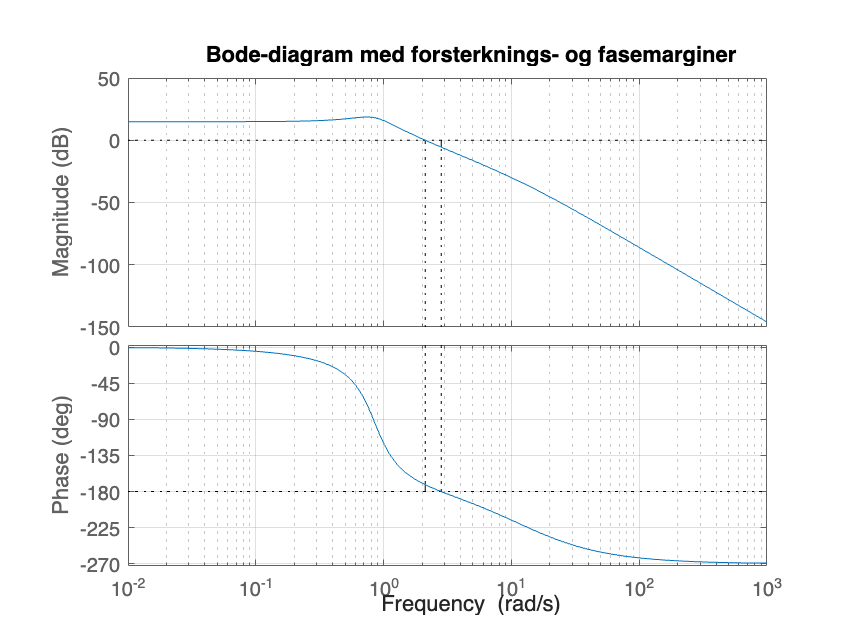


% Ekstra: Plot Bode-diagram for å visualisere marginene
figure;
margin(G);
title('Bode-diagram med forsterknings- og fasemarginer');
grid on;

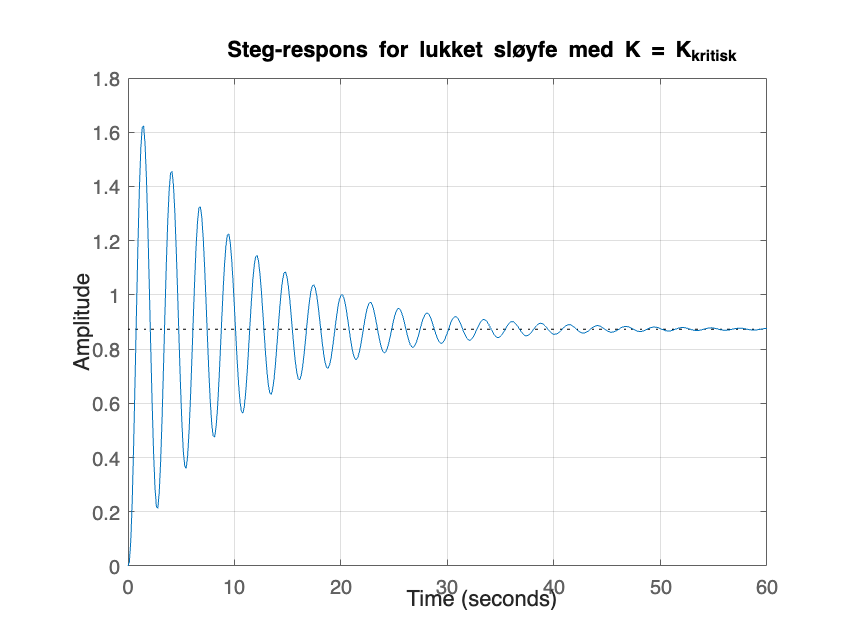


% Ekstra: Plot steg-respons for å visualisere systemets respons ved K = K_kritisk
G_critical = tf([50 * K_kritisk], denominator);
figure;
step(feedback(G_critical, 1)); % Lukket sløyfe med enhet tilbakekobling
title('Steg-respons for lukket sløyfe med K = K_kritisk');
grid on;